# Plot of motor speeds and sensor values

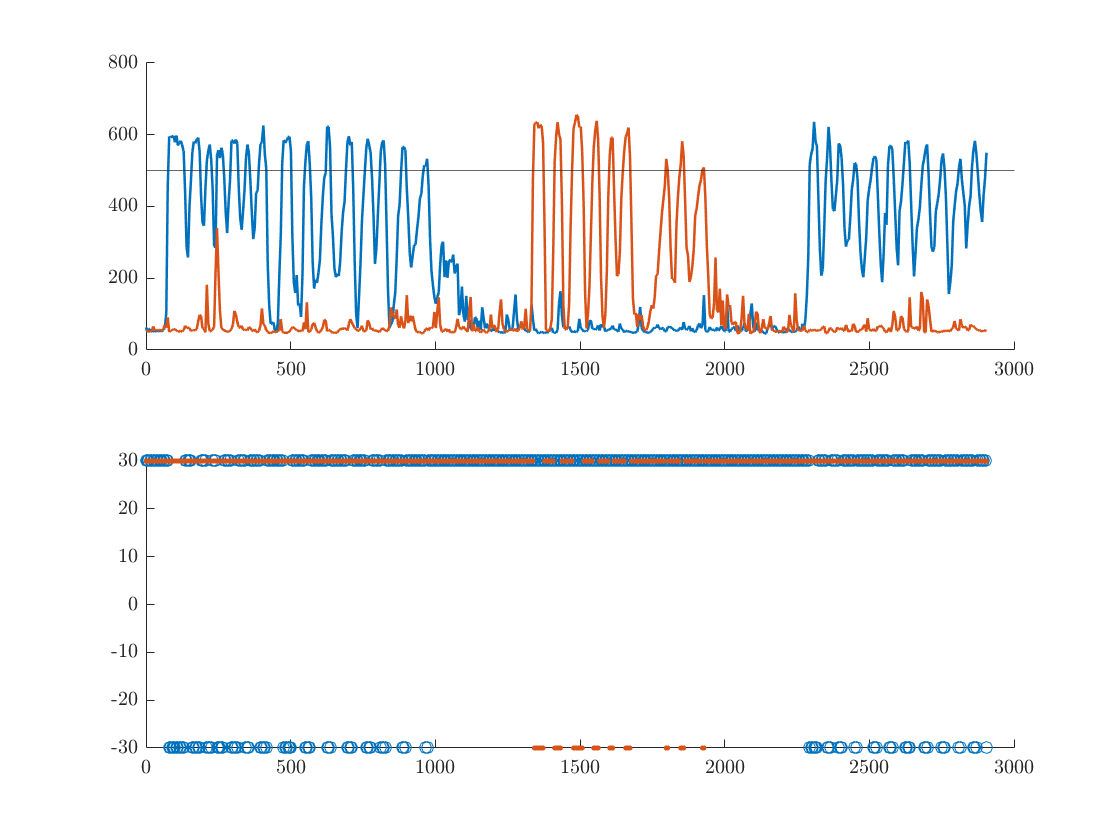

clear
load("line_follower_data.mat", "line_follower_data");

dt = 5; % ms

data = table2array(line_follower_data);
data = data(1400/dt:end, :);

IR_l = data(:, 1);
IR_r = data(:, 2);
online_l = data(:, 3);
online_r = data(:, 4);
motor_l = data(:, 5);
motor_r = data(:, 6);

t = linspace(0, size(data, 1)*dt, size(data, 1));

figure
init_prettyplot();

subplot(2, 1, 1)
hold on
% yyaxis left
plot(t, IR_l)
plot(t, IR_r)
yline(500)

subplot(2, 1, 2)
hold on
% yyaxis right
scatter(t, motor_l)
scatter(t, motor_r, ".")

% plot(t, motor_l)
% plot(t, motor_r)
% ylim([0, 2])



function init_prettyplot()
    set(groot,'defaulttextinterpreter','latex');
    set(groot,'defaultLegendInterpreter','latex');
    set(groot,'defaultAxesTickLabelInterpreter','latex');  
    set(0, 'DefaultLineLineWidth', 1.25);
end

function prettify_plot()
    ax = gca;
    ax.FontSize = 14;
    ax.TitleFontSizeMultiplier = 1.25;
end